# MatLab Term Test 2 Prep

### Syntax

#### Vectors and Matrices

you can use `linspace` to create $1\times n$ vectors

x = linspace(0,10,100); % 100 evenly spaced points between 0 and 10
% Find the transpose
x_transpose = x'; % n x 100 vector

Create some matrix:

A = [1 1 1 ; 2 2 2 ; 3 3 3] % seperate rows by semi-colon

A =      1     1     1
     2     2     2
     3     3     3


####  Solving a linear system

Suppose `A = [1 1; 2 2] and `$A\vec{x} = b$. Then you can computer $x$ using Matlab's backslash operater:

A = [1 1; 3 2]

A =      1     1
     3     2


b = [6 ; 4]

b =      6
     4



sol = A\b % output the solution of the system.

sol =     -8
    14


#### Plotting functions

Say you want to plot$y = 10x+7$. Generate your domain using `linspace`

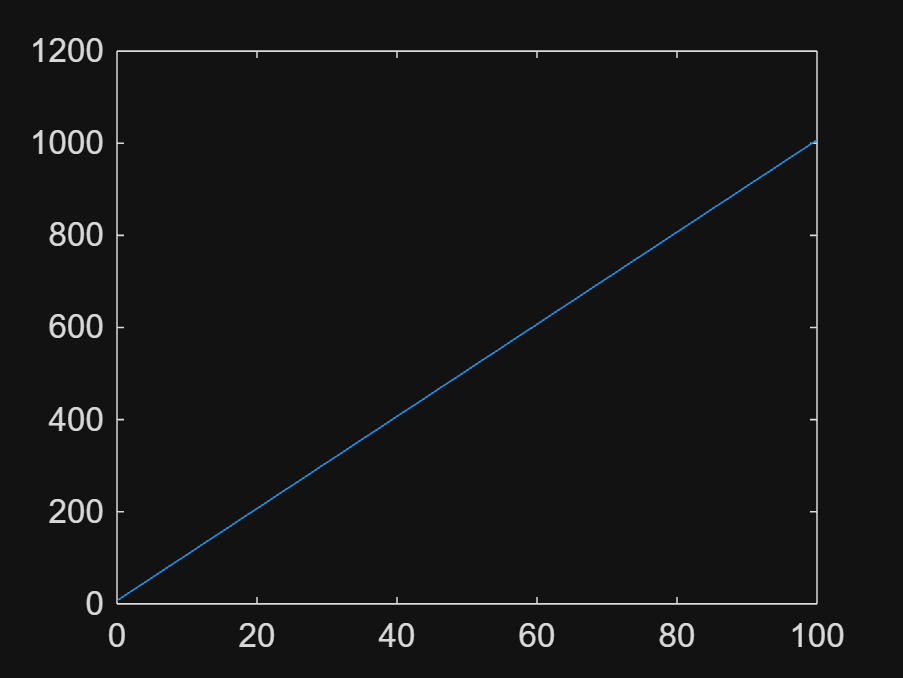

x = linspace(0, 100, 100);
% generate y plot
y = 10*x + 7;
plot(x,y); % plots x against y

Suppose you want to generate multiple plots on the same graph. Use `hold on`

f1 = figure % create a figure and name it f1

f1 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [411 242 560 420]
       Units: 'pixels'

  Show all properties

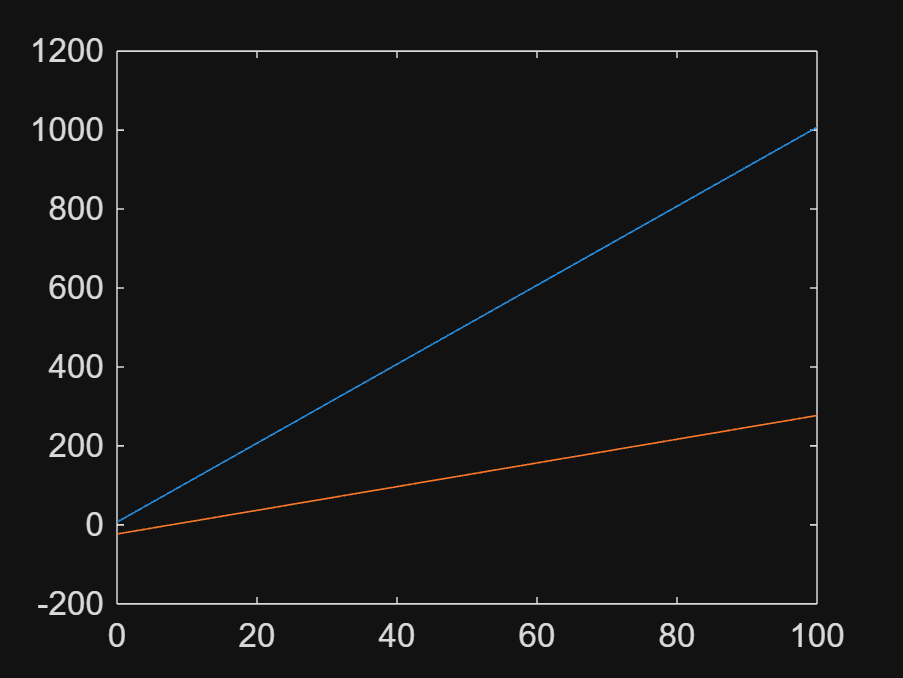

y1 = 10*x + 7;
y2 = 3*x-23;
plot(x,y1)
hold on
plot(x,y2)
hold off % put hold off or it continues plotting on the same plot

If you want to plot a point, use the `plot`

% plot the point 5,6
plot(5,6,'ro')

You can also label plots

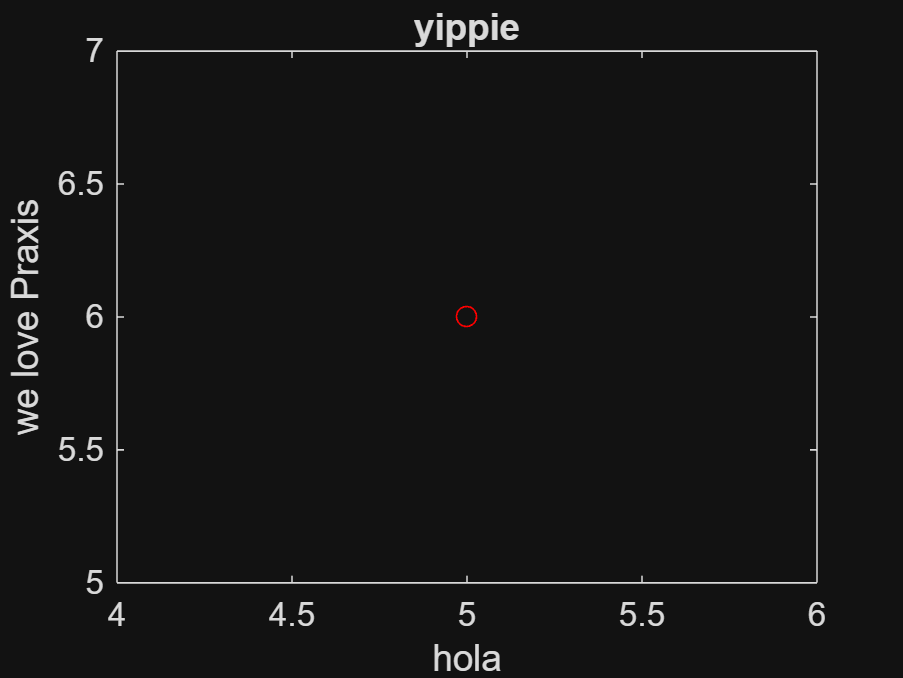

xlabel("hola")
ylabel("we love Praxis")
title("yippie")

### For loops

Indices start at **1 not 0. **Here's a `for` loop. Note both bounds are inclusive

for i = 0:5
    i
end % must have `end` or you'll get error

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

To specify step size, add middle parameter

for i = 0:0.2:5
    i
end

i = 0

i = 0.2000

i = 0.4000

i = 0.6000

i = 0.8000

i = 1

i = 1.2000

i = 1.4000

i = 1.6000

i = 1.8000

i = 2

i = 2.2000

i = 2.4000

i = 2.6000

i = 2.8000

i = 3

i = 3.2000

i = 3.4000

i = 3.6000

i = 3.8000

i = 4

i = 4.2000

i = 4.4000

i = 4.6000

i = 4.8000

i = 5

You can use nested `for` loops to, `for` example, populate a matrix

mat = []; % initalize an empty matrix
for i = 1:5 % you cannot have 0 index
    for j = 1:5
        mat(i,j) = 5;
    end
end

mat = 5

mat =      5     5


mat =      5     5     5


mat =      5     5     5     5


mat =      5     5     5     5     5


mat =      5     5     5     5     5
     5     0     0     0     0


mat =      5     5     5     5     5
     5     5     0     0     0


mat =      5     5     5     5     5
     5     5     5     0     0


mat =      5     5     5     5     5
     5     5     5     5     0


mat =      5     5     5     5     5
     5     5     5     5     5


mat =      5     5     5     5     5
     5     5     5     5     5
     5     0     0     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     0     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     0     0     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     0     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     0     0     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     0     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     0     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     0


mat =      5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5
     5     5     5     5     5


Something interesting: if you remove the semi-colon, you'll see that once a new row is started the entire row is populated with `0`. 

### Linear Algebra Stuff

#### Least Squares Regression

long winded and rambly explanation sorry, didn't have time to plan out the explanation.

If we have a set of data points that land on some function exactly, we know how to determine the regression line (the data points form a consistent matrix vector system which we can solve for).

Measurement data does not often fit a function exactly so the solution to its matrix-vector system is inconsistent. We still want to find a regression line, which we can do by allowing error. The best regression line has the smallest error.

Start by setting our linear system. We have a list of $(x,y)$ coordinate pairs and know that the trend line is $y = a + bx$. Let's store this info with matrices and vectors (I haven't thought much on how to think about matrices as linear transformations, but for now just use matrices+vectors to store information compactly).

Specifically, we want the form $A\vec{c} = \vec{y}$ to spit out $y=a+bx$. Use what we know about matrix vector multiplication to get this behaviour, i.e. for a data set $(x_1, y_1), (x_2, y_2),..,(x_n,y_n)$ set 